Live script to produce BER vs SNR plots for OFDM signals of varying modulation order

clc;
clear all;

MODULATION_FORMAT = 'QAM';

TOTAL_NUM_BITS = 1e6;

NUM_SUBCARRIERS = 15;

CYCLIC_PREFIX_LENGTH = 1/4; % Given as a ratio of symbol length

assert(mod((2+2*NUM_SUBCARRIERS)*CYCLIC_PREFIX_LENGTH,1) == 0);


MOD_ORDER_VALS = [4; 16; 64]; % powers of 2 from 4 to 512

snr_ratios = linspace(1,25,50);
ber_vals = zeros(length(snr_ratios), length(MOD_ORDER_VALS));
normalised_snr_vals = zeros(length(snr_ratios), length(MOD_ORDER_VALS));

for mod_order_index = 1:1:length(MOD_ORDER_VALS)
    
    num_bits_per_symbol = log2(MOD_ORDER_VALS(mod_order_index));
    
    num_symbols_per_carrier = round((TOTAL_NUM_BITS/num_bits_per_symbol)/NUM_SUBCARRIERS);
    
    [modulated_signal, symbol_stream] = generateRandModSignal(num_symbols_per_carrier, MOD_ORDER_VALS(mod_order_index), NUM_SUBCARRIERS, MODULATION_FORMAT);
    
    ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);
    
    OFDM_SYMBOL_LENGTH = ((2+2*NUM_SUBCARRIERS))*(1+CYCLIC_PREFIX_LENGTH);
    
    normalised_snr_vals(:, mod_order_index) = normaliseSNR(num_bits_per_symbol, num_bits_per_symbol, snr_ratios);
    
    for snr_index = 1:1:length(snr_ratios)
        ofdm_signal_with_noise = awgn(ofdm_signal,snr_ratios(snr_index),'measured');
        extracted_modulated_signal = convertFromOFDMSignal(ofdm_signal, NUM_SUBCARRIERS, CYCLIC_PREFIX_LENGTH);
        extracted_modulated_signal_with_noise = awgn(extracted_modulated_signal, snr_ratios(snr_index), 'measured');
        extracted_stream = demodSignal(extracted_modulated_signal_with_noise, MOD_ORDER_VALS(mod_order_index), MODULATION_FORMAT);
        [num_bit_errors, ber_vals(snr_index, mod_order_index), num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream);
    end
end

semilogy(snr_ratios, ber_vals, '^');

hold on;
% name_array = ['4-QAM.csv'; '16-QAM.csv'; '64-QAM.csv']
file_names = char({'4-QAM.csv', '16-QAM.csv', '64-QAM.csv'});

for file_index = 1:1:size(file_names, 1)
    file_name = file_names(file_index, :);
    data = csvread(file_name);
    
    semilogy(data(:,1), data(:,2), '-');
    hold on;
end

hold off;

my_data_labels = num2str(MOD_ORDER_VALS, '%d');
% full_legend = [my_data_labels; file_names]

leg = legend('4 (Data)', '16 (Data)', '64 (Data)', '4 (Theory)', '16 (Theory)', '64 (Theory)', 'Location','southwest');
xlabel('SNR (dB)')
ylabel('BER')
xlim([0,25])
ylim([0.00001,1])
title(leg,strcat(MODULATION_FORMAT, ' Order'))
legend('boxoff');
filename = strcat('figures/', MODULATION_FORMAT, '_BER_vs_SNR_compared_', num2str(TOTAL_NUM_BITS, 1), '_bits_', timestampString(), '.pdf')

filename = 'figures/QAM_BER_vs_SNR_compared_1e+06_bits_200612_131749.pdf'

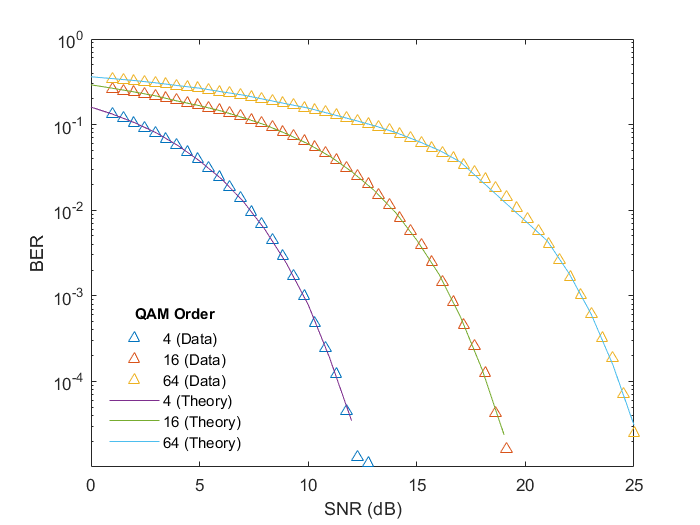

exportgraphics(gcf, filename)